# Generacion de puntos en Espacio de configuración

## Puntos deseados en Espacio cartesiano 2D.

PuntosC = ...    %Lista de puntos para trayectoria x,y,x1,y1...
[40,0,...       %Punto inicial
 -15,15,5,-15,...  % Puntos vía
  40,0];         %Punto final

% Longitud de los eslabones
L1=20; L2=20;   %parametros Longitud para cinematica inversa
% inicializo theta
theta1=[];
theta2=[];


## Obtención de puntos en Espacio de articulación/configuración

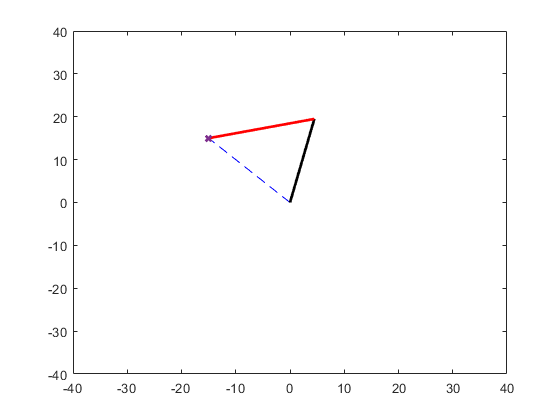

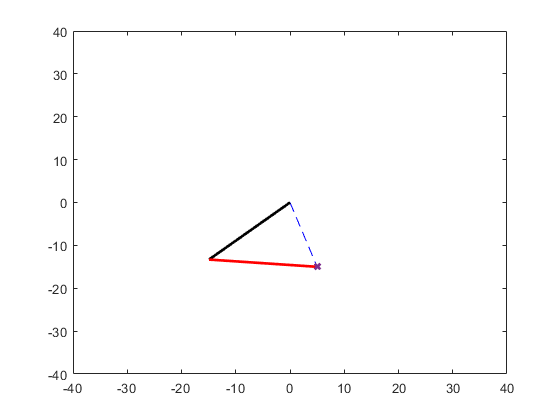

% obteniendo los puntos en el espacio de configuracion
for i=1:length(PuntosC)/2
    figure(i) %graficar en figuras distintas
%     Mapeo de puntos en Espacio Carteciano
%     hacia el Espacio de configuración
    [theta1(i),theta2(i)]=invRR(PuntosC(i*2-1),PuntosC(i*2),L1,L2,1); %1 codo abajo
end

# Suavizar la trayectoria por medio de:

- Spline cúbico de matlab

% run 'TrayectoriaSplineMatlab.mlx'

Salidas

articulacion1=stheta1;

articulacion2=stheta2;

- Spline cúbico con matrices de 4 puntos 

run 'spline3_theta1.mlx'

y1 =     1.3444    1.2436    1.1099    0.9473    0.7598    0.5513    0.3257    0.0871   -0.1608   -0.4138   -0.6682   -0.9198   -1.1649   -1.3994   -1.6193   -1.8208   -1.9999   -2.1527   -2.2752   -2.3634   -2.4135


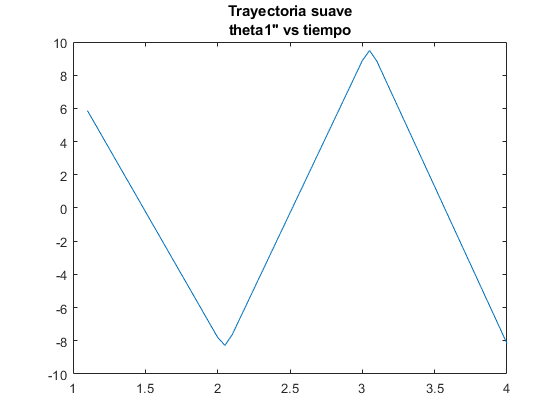

y1 =     2.0236    2.1331    2.2346    2.3278    2.4123    2.4879    2.5542    2.6110    2.6577    2.6943    2.7203    2.7354    2.7393    2.7317    2.7122    2.6806    2.6365    2.5796    2.5096    2.4261    2.3288


run 'spline3_theta2.mlx'

Salidas

articulacion1=Y1;

articulacion2=Y2;

- Spline Orden 5 con matrices de 4 puntos

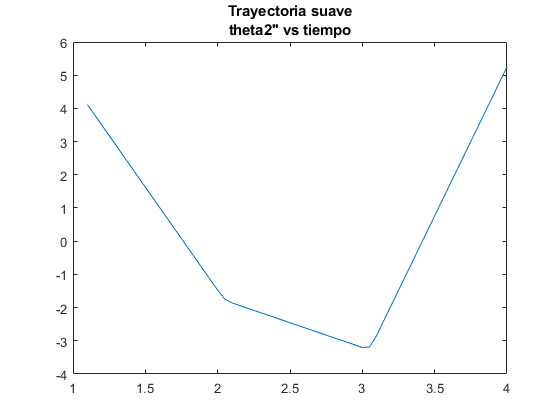

run 'spline5_theta1.mlx'

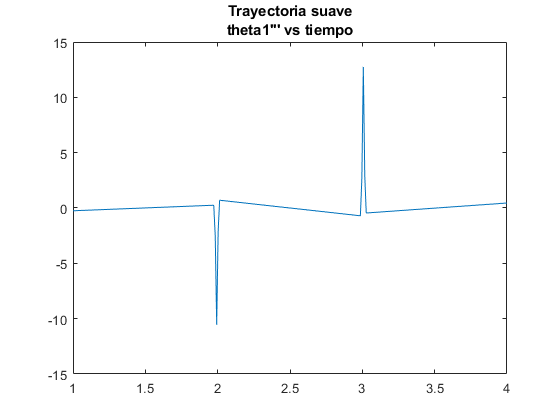

run 'spline5_theta2.mlx'

Salidas

articulacion1=s5_Y1;

articulacion2=s5_Y2;

Programado por: Alfredo José Maussa Caballero.

Supervisado: Sebastián Jiménez Gómez